# Geometrically nonlinear L beam model

We consider an example as follows. The structure consists of two beams connected via a revolute joint. A harmonic excitation is applied at the midspan of the horizontal beam.

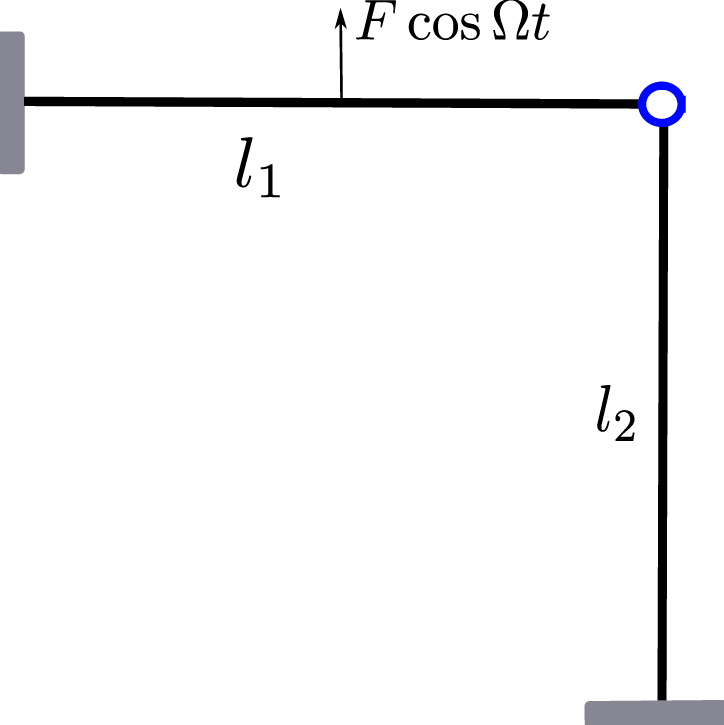

This example is motivated by the internally resonant T-beam structure described here

Dou, S., Strachan, B. S., Shaw, S. W., & Jensen, J. S. (2015). Structural optimization for nonlinear dynamic response. *Philosophical Transactions of the Royal Society A: Mathematical, Physical and Engineering Sciences*, *373*(2051). [https://doi.org/10.1098/RSTA.2014.0408](https://doi.org/10.1098/RSTA.2014.0408)

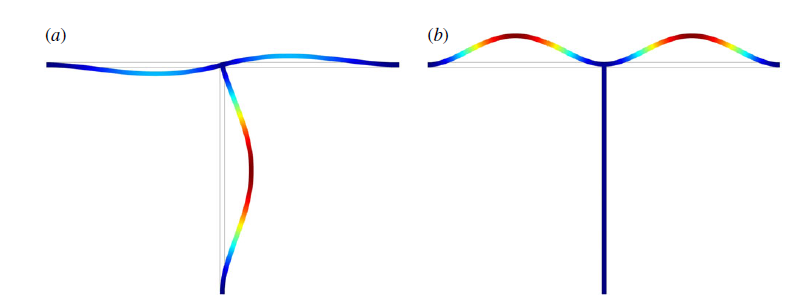

We model this structure as a union of two straight von Karman beams which results in DAE as follows


$$M\ddot{q}+C\dot{q}+Kq+G^T\lambda=F^{\mathrm{ext}}\cos\Omega t,\\ Gq=0.$$


where 


$$M=\mathrm{diag}(M_1,M_2),\quad C=\mathrm{diag}(C_1,C_2),\quad K=\mathrm{diag}(K_1,K_2)$$


and the linear configuration constraints $Gq=0$ denote the continuity condition of displacements at the joint.

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). *Zenodo*. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

#### Generate model

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:00
Assembling external force vector


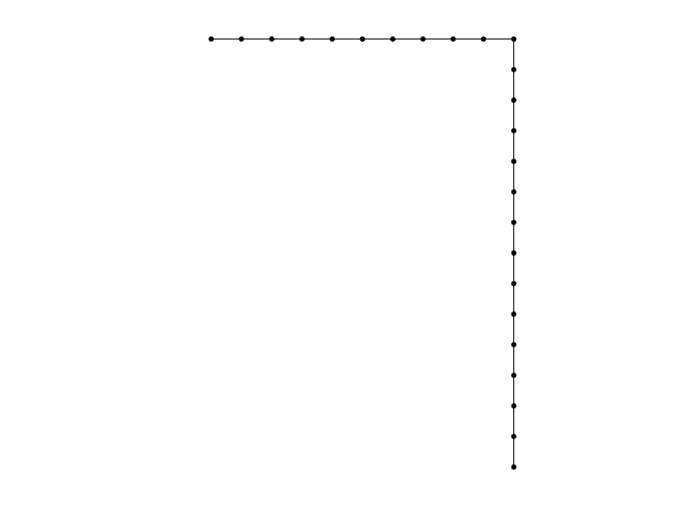

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:00
Assembling external force vector


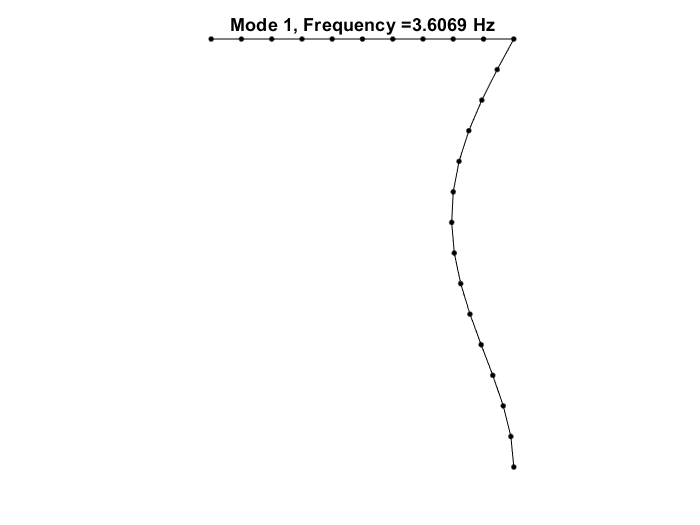

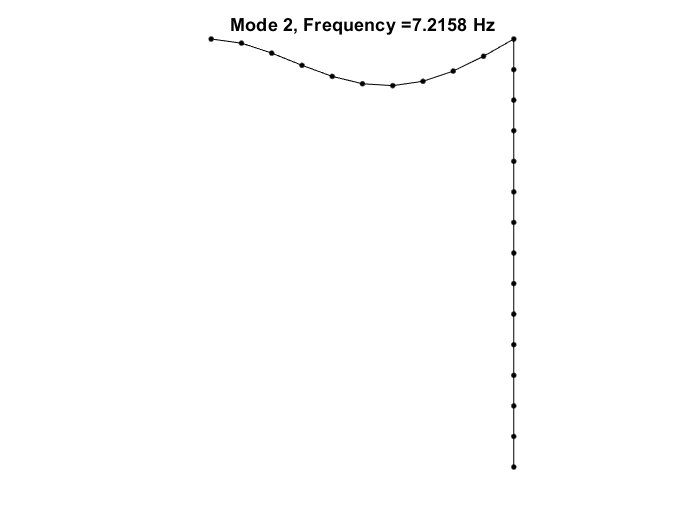

clear all
nElements1 = 10;
nElements2 = 14;
[B,A,fnl,fext,outdof] = build_model_1st(nElements1,nElements2);

n = size(A,1);
disp(['Phase space dimensionality = ' num2str(n)])

Phase space dimensionality = 146


#### Dynamical system setup 

DS = DynamicalSystem();
set(DS,'B',B,'A',A,'fnl',fnl);
set(DS.Options,'Emax',8,'Nmax',10,'notation','multiindex')
% due to the added configuration constraints, 
% the updated damping matrix is not propotional anymore
set(DS.Options,'RayleighDamping',false,'sigma',0.5);
% add forcing
epsilon = 1e-1*1e1;
kappas = [1; -1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

#### Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0004 + 0.2266i
  -0.0004 - 0.2266i
  -0.0015 + 0.4534i
  -0.0015 - 0.4534i
  -0.0039 + 0.7344i
  -0.0039 - 0.7344i
  -0.0154 + 1.4693i
  -0.0154 - 1.4693i



S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex');
resonant_modes = [1 2 3 4]; % choose master spectral subspace
mFreq = [1/2 1];            % internal resonance relation vector
order = 5;                  % SSM expansion order

#### SSM_epSweeps: continuation of FRC w.r.t $\Omega$ at sampled $\{\epsilon_i\}$

(near) outer resonance detected for the following combination of master eigenvalues
     1     0     1     0
     0     1     2     0
     3     0     0     0
     1     0     2     1
     2     1     1     0
     0     1     3     1
     1     2     2     0
     3     0     1     1
     4     1     0     0
     0     3     3     0
     1     0     3     2
     2     1     2     1
     3     2     1     0
     5     0     0     1
     0     1     4     2
     1     2     3     1
     2     3     2     0
     3     0     2     2
     4     1     1     1
     5     2     0     0
     0     3     4     1
     1     0     4     3
     1     4     3     0
     2     1     3     2
     3     2     2     1
     4     3     1     0
     5     0     1     2
     6     1     0     1
     0     1     5     3
     0     5     4     0
     1     2     4     2
     2     3     3     1
     3     0     3     3
     3     4     2     0
     4     1     2     2
     5     2     1     1
     6     3    

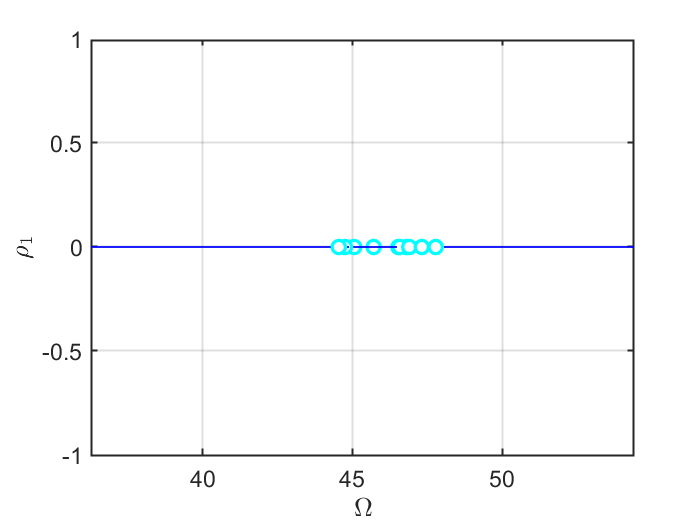

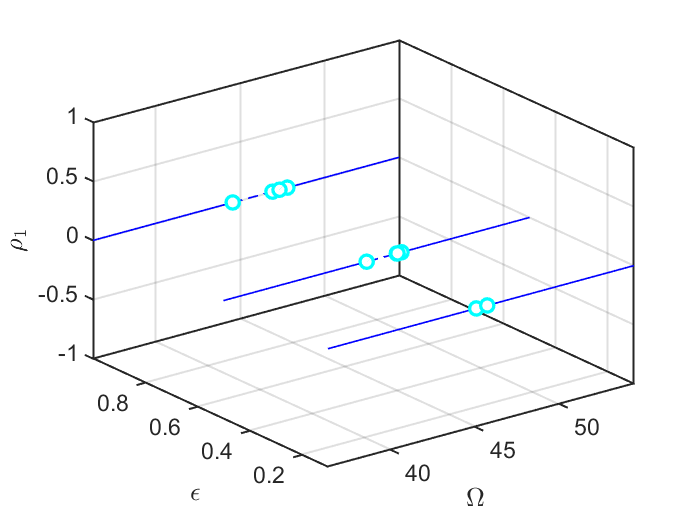

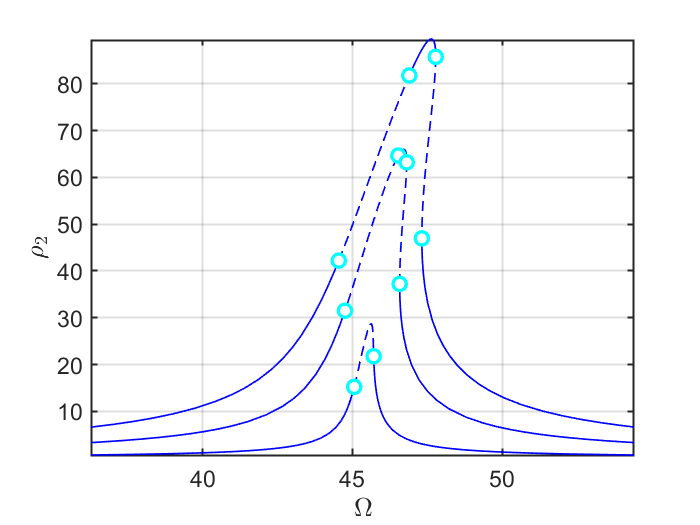

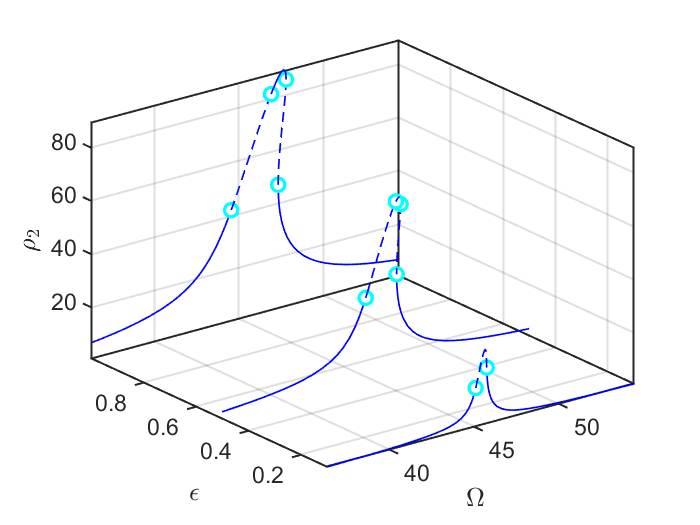

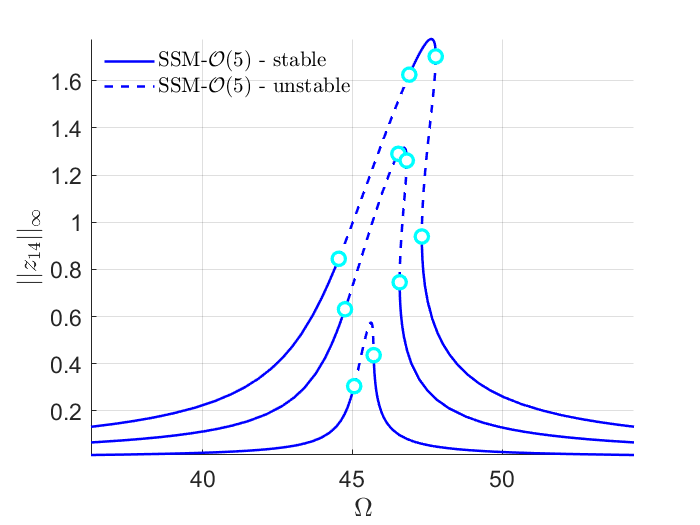

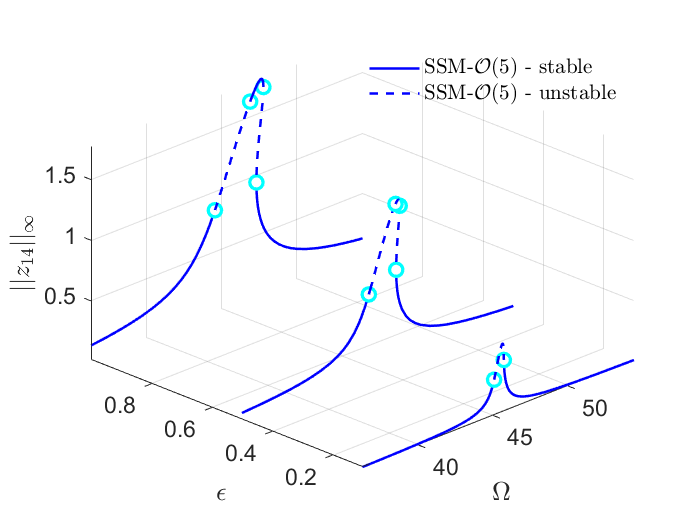

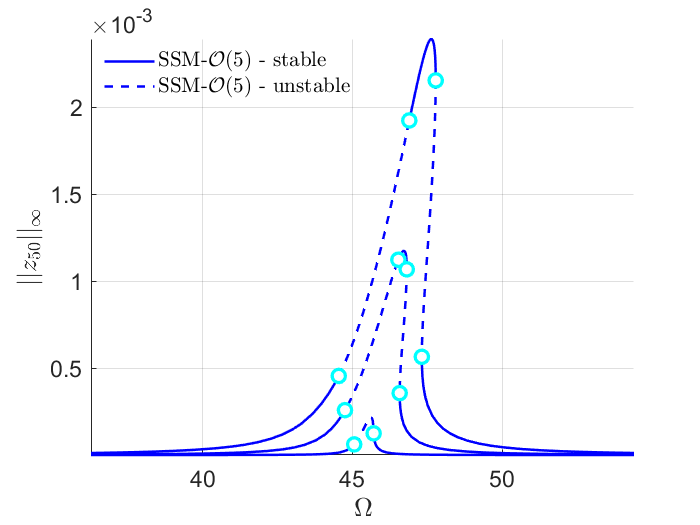

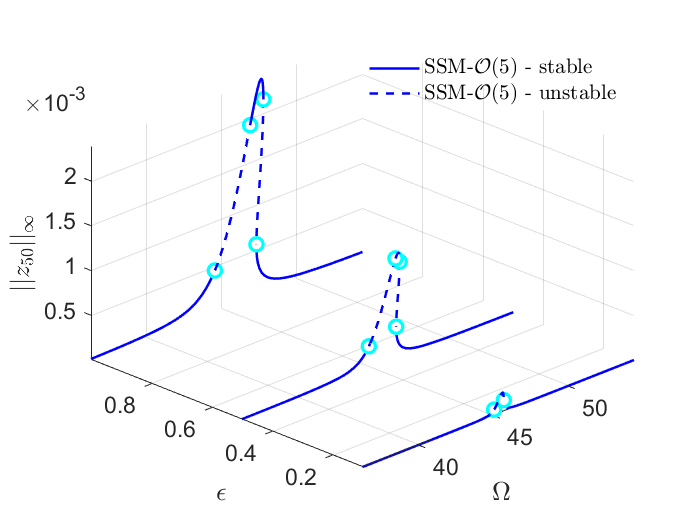

set(S.FRCOptions,'sampStyle', 'cocoBD');                         % sampling style
set(S.contOptions, 'PtMX', 200, 'h_max', 50,'h_min',0.01,'MaxRes',1);    % continuation setting
set(S.FRCOptions, 'nCycle',5000, 'initialSolver', 'fsolve');     % initial solution scheme
set(S.FRCOptions, 'coordinates', 'cartesian');                       % two coordinate representations
set(S.Options,'contribNonAuto',false);
epsSamp = [1e-1 5e-1 1]*epsilon;
freqRange = [0.8 1.2]*imag(D(3));
S.SSM_epSweeps('sweeps',resonant_modes,order,mFreq,epsSamp,freqRange,outdof);

#### Check the convergence of FRC with increasing orders

(near) outer resonance detected for the following combination of master eigenvalues
     1     0     1     0
     0     1     2     0
     3     0     0     0
     1     0     2     1
     2     1     1     0
     0     1     3     1
     1     2     2     0
     3     0     1     1
     4     1     0     0
     0     3     3     0
     1     0     3     2
     2     1     2     1
     3     2     1     0
     5     0     0     1
     0     1     4     2
     1     2     3     1
     2     3     2     0
     3     0     2     2
     4     1     1     1
     5     2     0     0
     0     3     4     1
     1     0     4     3
     1     4     3     0
     2     1     3     2
     3     2     2     1
     4     3     1     0
     5     0     1     2
     6     1     0     1
     0     1     5     3
     0     5     4     0
     1     2     4     2
     2     3     3     1
     3     0     3     3
     3     4     2     0
     4     1     2     2
     5     2     1     1
     6     3    

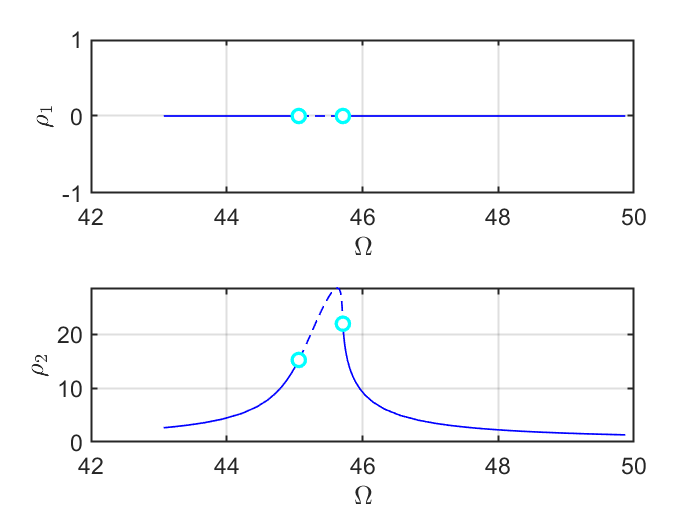

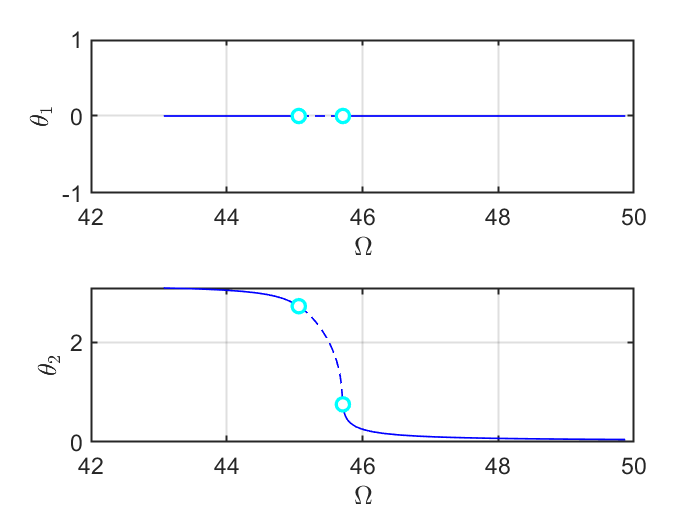

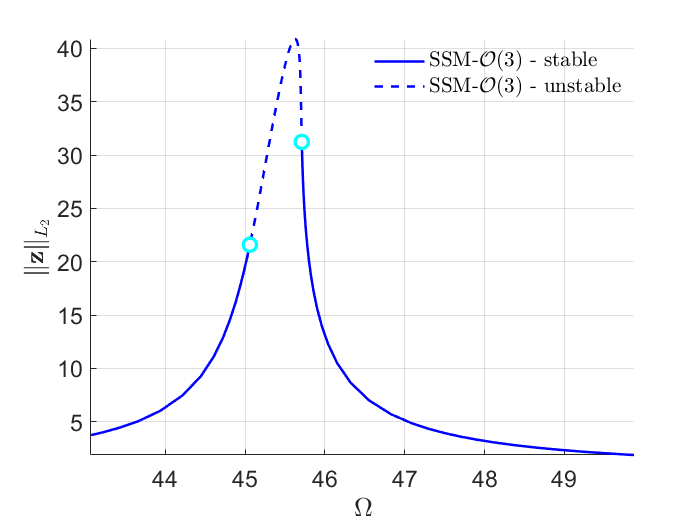

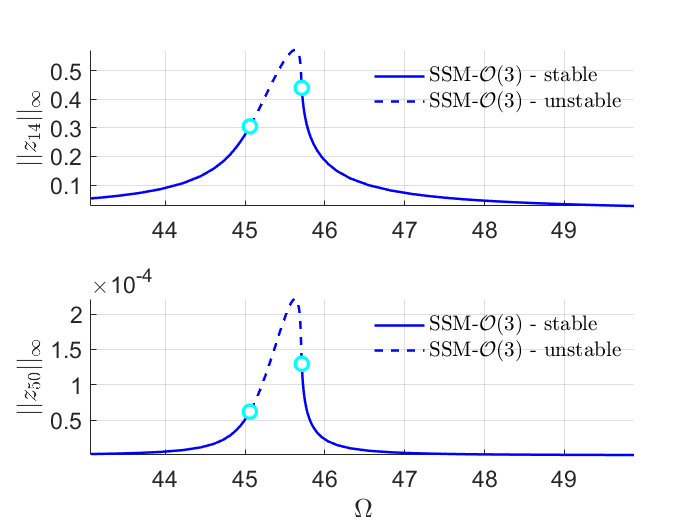

% increase order to check convergence
sol = ep_read_solution('sweepseps1.ep',1);
epsilon = sol.p(2);
kappas = [1; -1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);
omegaRange = [0.95 1.1]*imag(D(3));
start = tic;
FRC_O3 = S.SSM_isol2ep('isol-3', resonant_modes, order-2, mFreq,...
    'freq', omegaRange, outdof, {sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     1     0     1     0
     0     1     2     0
     3     0     0     0
     1     0     2     1
     2     1     1     0
     0     1     3     1
     1     2     2     0
     3     0     1     1
     4     1     0     0
     0     3     3     0
     1     0     3     2
     2     1     2     1
     3     2     1     0
     5     0     0     1
     0     1     4     2
     1     2     3     1
     2     3     2     0
     3     0     2     2
     4     1     1     1
     5     2     0     0
     0     3     4     1
     1     0     4     3
     1     4     3     0
     2     1     3     2
     3     2     2     1
     4     3     1     0
     5     0     1     2
     6     1     0     1
     0     1     5     3
     0     5     4     0
     1     2     4     2
     2     3     3     1
     3     0     3     3
     3     4     2     0
     4     1     2     2
     5     2     1     1
     6     3    

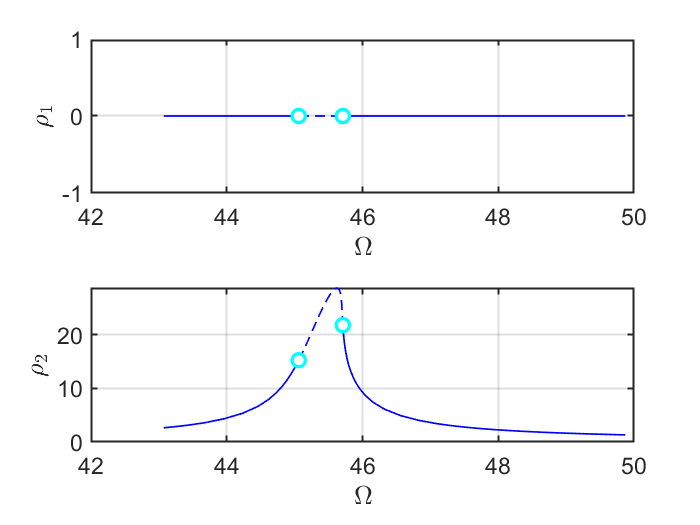

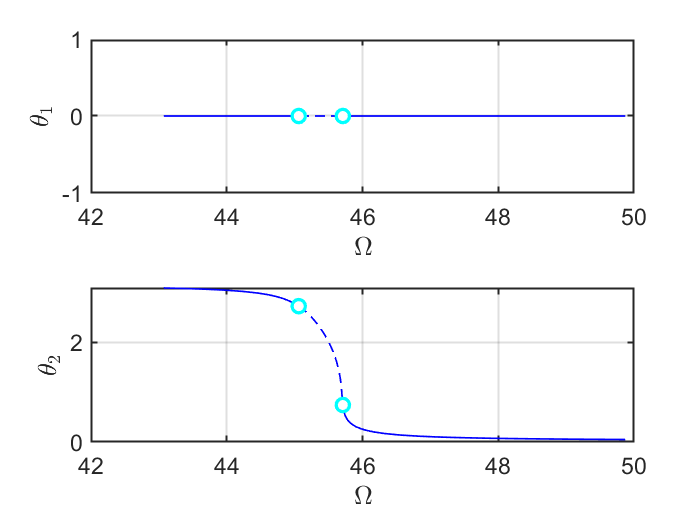

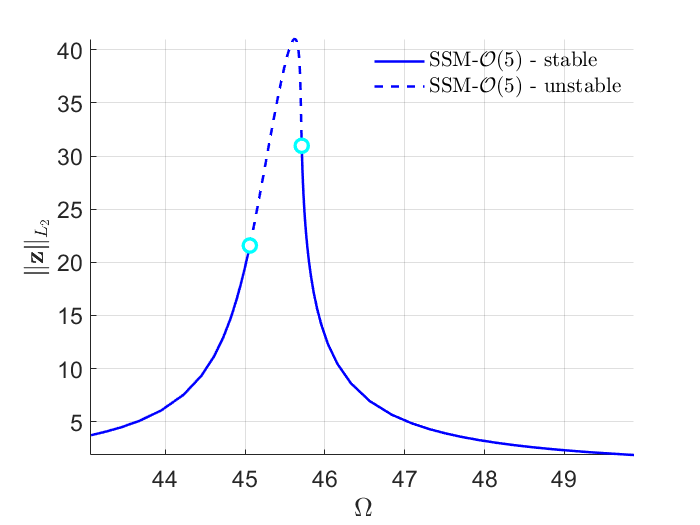

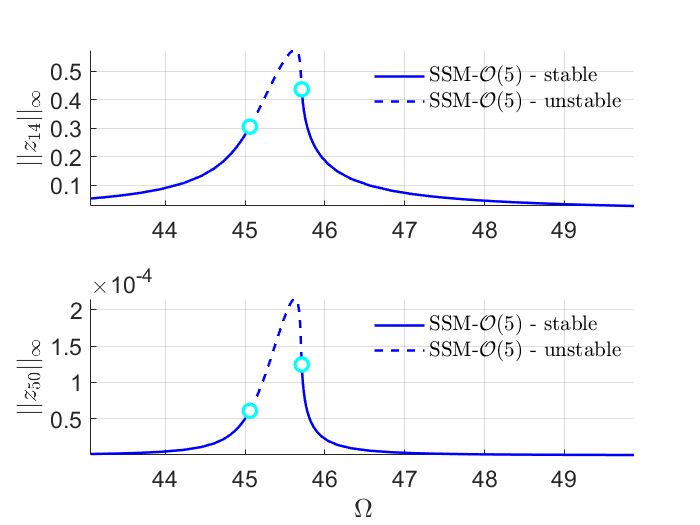

timings.FRC_O3 = toc(start);

start = tic;
FRC_O5 = S.SSM_isol2ep('isol-5', resonant_modes, order, mFreq,...
    'freq', omegaRange, outdof, {sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     1     0     1     0
     0     1     2     0
     3     0     0     0
     1     0     2     1
     2     1     1     0
     0     1     3     1
     1     2     2     0
     3     0     1     1
     4     1     0     0
     0     3     3     0
     1     0     3     2
     2     1     2     1
     3     2     1     0
     5     0     0     1
     0     1     4     2
     1     2     3     1
     2     3     2     0
     3     0     2     2
     4     1     1     1
     5     2     0     0
     0     3     4     1
     1     0     4     3
     1     4     3     0
     2     1     3     2
     3     2     2     1
     4     3     1     0
     5     0     1     2
     6     1     0     1
     0     1     5     3
     0     5     4     0
     1     2     4     2
     2     3     3     1
     3     0     3     3
     3     4     2     0
     4     1     2     2
     5     2     1     1
     6     3    

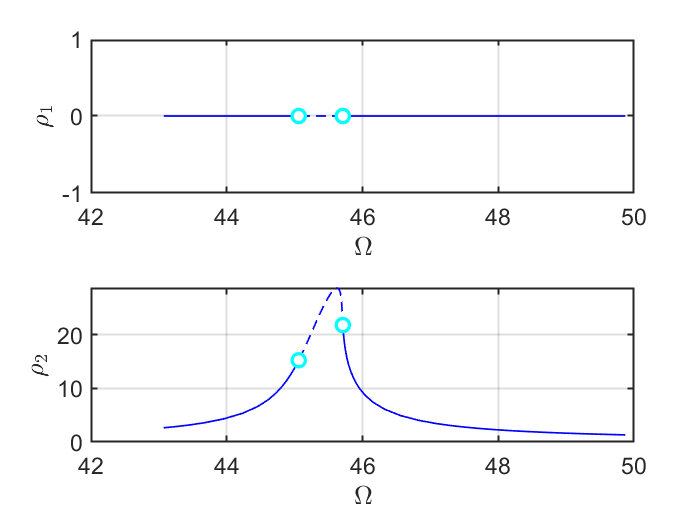

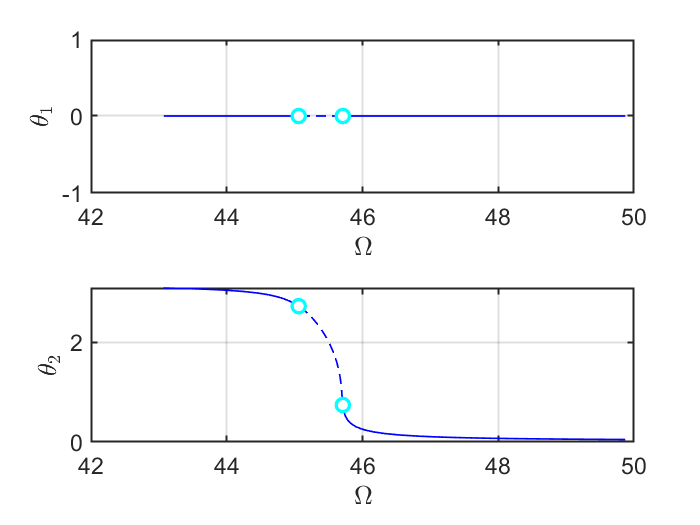

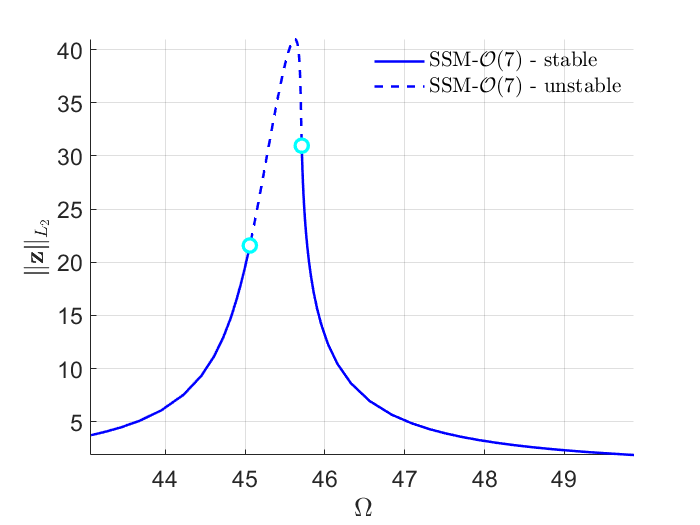

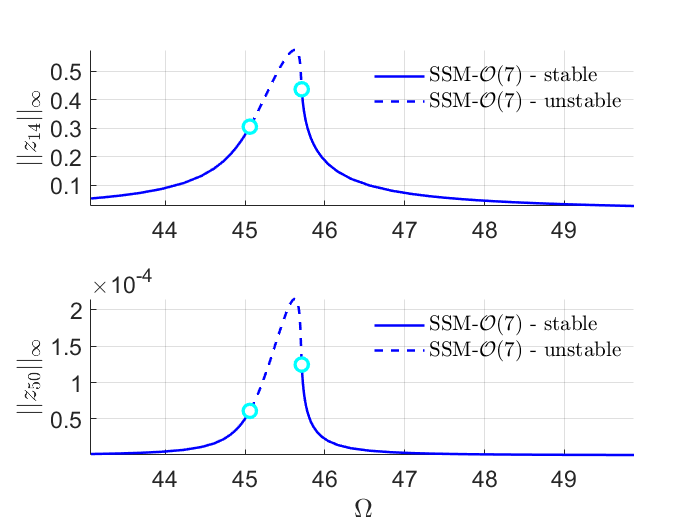

timings.FRC_O5 = toc(start);

start = tic;
FRC_O7 = S.SSM_isol2ep('isol-7', resonant_modes, order+2, mFreq,...
    'freq', omegaRange, outdof, {sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     1     0     1     0
     0     1     2     0
     3     0     0     0
     1     0     2     1
     2     1     1     0
     0     1     3     1
     1     2     2     0
     3     0     1     1
     4     1     0     0
     0     3     3     0
     1     0     3     2
     2     1     2     1
     3     2     1     0
     5     0     0     1
     0     1     4     2
     1     2     3     1
     2     3     2     0
     3     0     2     2
     4     1     1     1
     5     2     0     0
     0     3     4     1
     1     0     4     3
     1     4     3     0
     2     1     3     2
     3     2     2     1
     4     3     1     0
     5     0     1     2
     6     1     0     1
     0     1     5     3
     0     5     4     0
     1     2     4     2
     2     3     3     1
     3     0     3     3
     3     4     2     0
     4     1     2     2
     5     2     1     1
     6     3    

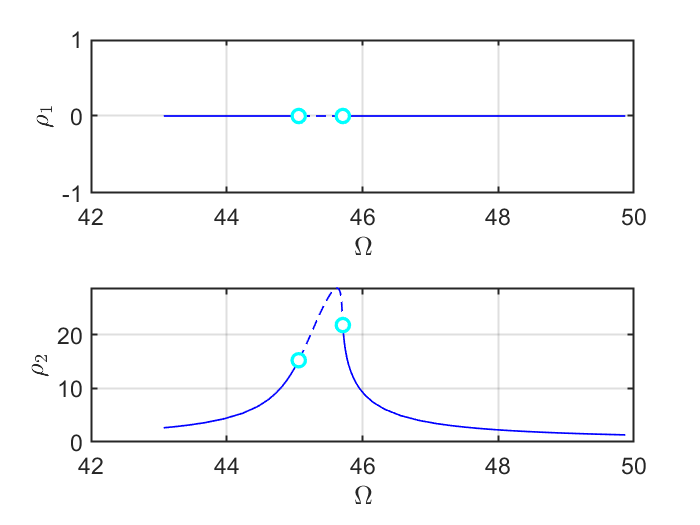

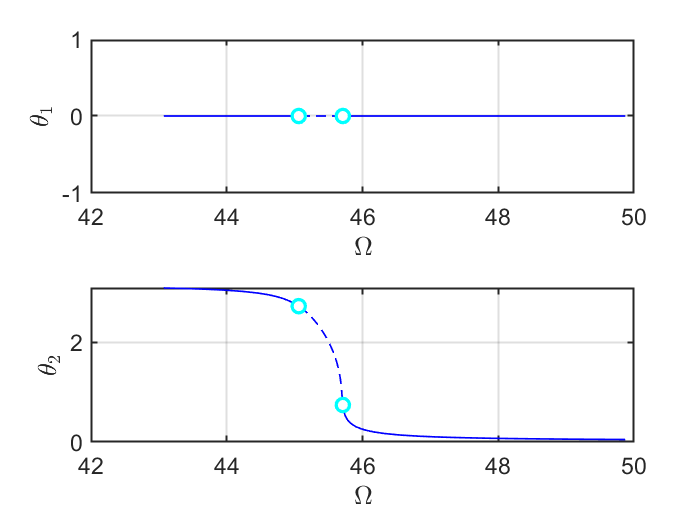

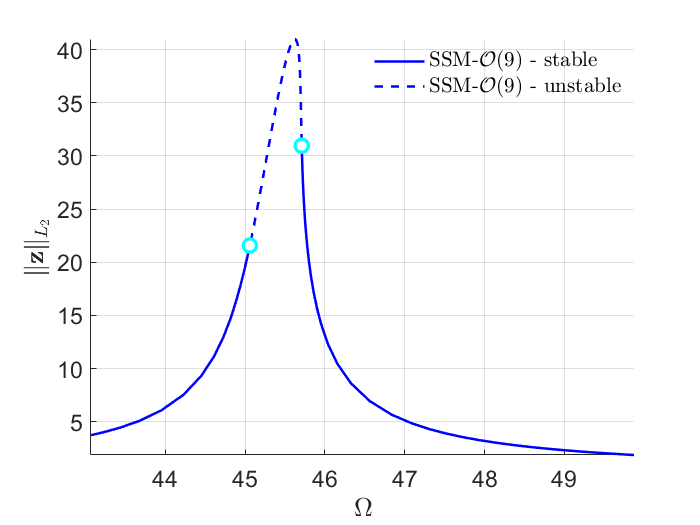

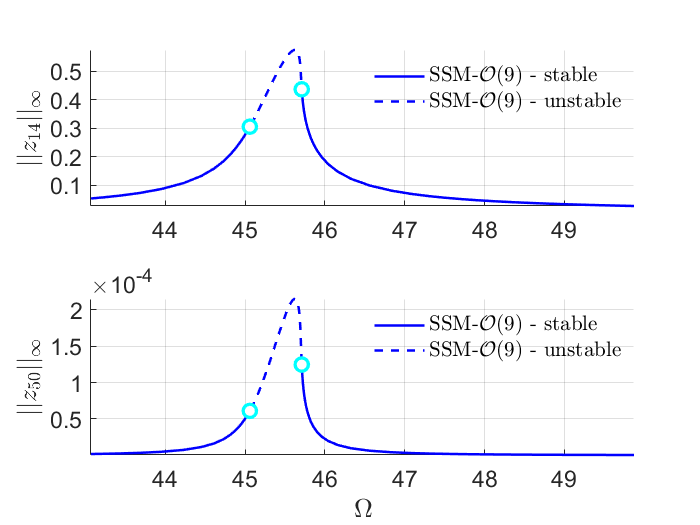

timings.FRC_O7 = toc(start);

start = tic;
FRC_O9 = S.SSM_isol2ep('isol-9', resonant_modes, order+4, mFreq,...
    'freq', omegaRange, outdof, {sol.p,sol.x});

timings.FRC_O9 = toc(start);


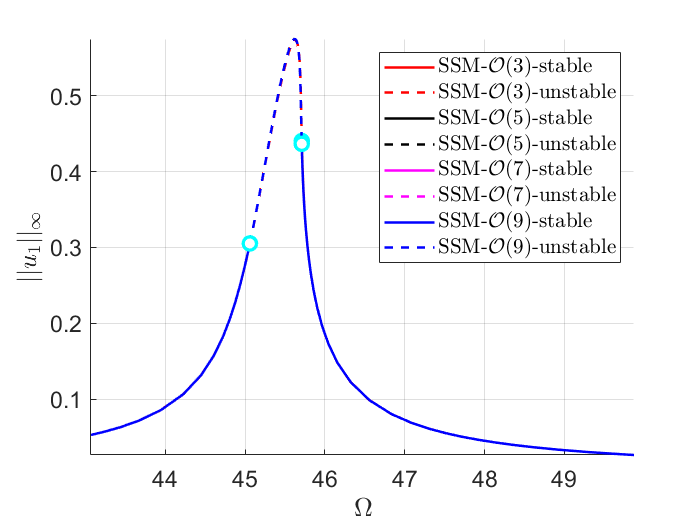

% plot results at the same figure
FRCs = {FRC_O3,FRC_O5,FRC_O7,FRC_O9};
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
color = {'r','k','m','b','g'};
figure;
ax1 = gca;
for k=1:numel(FRCs)
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    legs = ['SSM-$\mathcal{O}(',num2str(2*k+1),')$-unstable'];
    legu = ['SSM-$\mathcal{O}(',num2str(2*k+1),')$-stable'];
    hold(ax1,'on');
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||u_1||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
end

We observed the FRC converges well at O(5) approximation. Next we perform **branch switching** of branch points observed in this continuation run.

#### Secondary branches


 Run='o5-bp1.ep': Continue equilibria along secondary branch from label 4 of run isol-5.

 STEP      TIME        ||U||  LABEL  TYPE            om         Rez1         Rez2         Imz1         Imz2          eps
    0  00:00:00   6.7264e+01      1  EP      4.5060e+01   0.0000e+00  -1.3945e+01   0.0000e+00   6.1061e+00   1.0000e-01
    1  00:00:00   6.7264e+01      2  BP      4.5060e+01  -1.2129e-08  -1.3945e+01  -3.6018e-08   6.1061e+00   1.0000e-01
    1  00:00:00   6.7264e+01      3  FP      4.5060e+01  -5.0632e-03  -1.3945e+01  -1.5035e-02   6.1061e+00   1.0000e-01
   10  00:00:00   7.1489e+01      4          4.5138e+01  -5.6239e+00  -1.5238e+01  -1.3442e+01   8.5682e+00   1.0000e-01
   20  00:00:00   8.2500e+01      5          4.5345e+01  -1.6405e+01  -1.4853e+01  -2.2865e+01   1.8287e+01   1.0000e-01
   30  00:00:01   8.9415e+01      6          4.5507e+01  -2.6712e+01  -5.8219e+00  -2.2141e+01   2.6249e+01   1.0000e-01
   40  00:00:01   9.0509e+01      7          4.5601e+01  -3.36

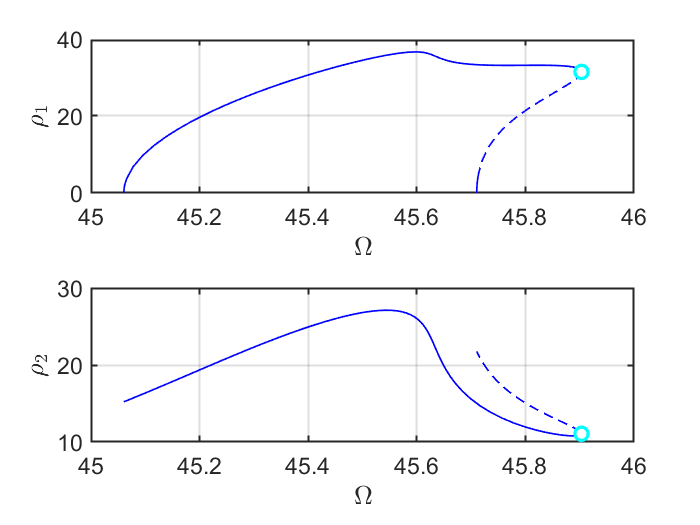

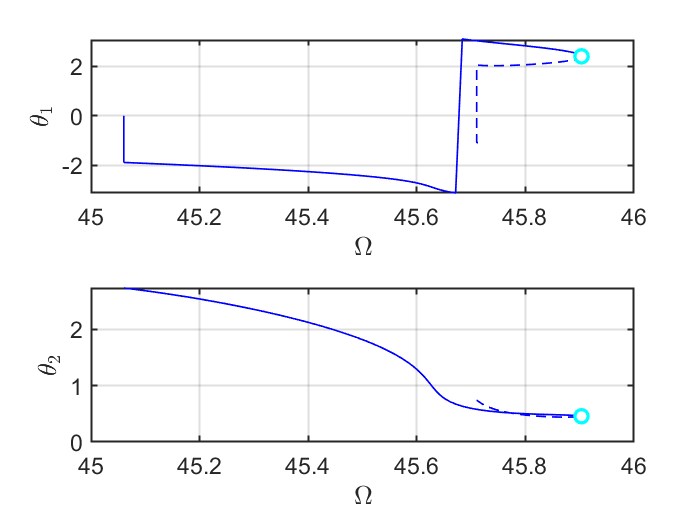

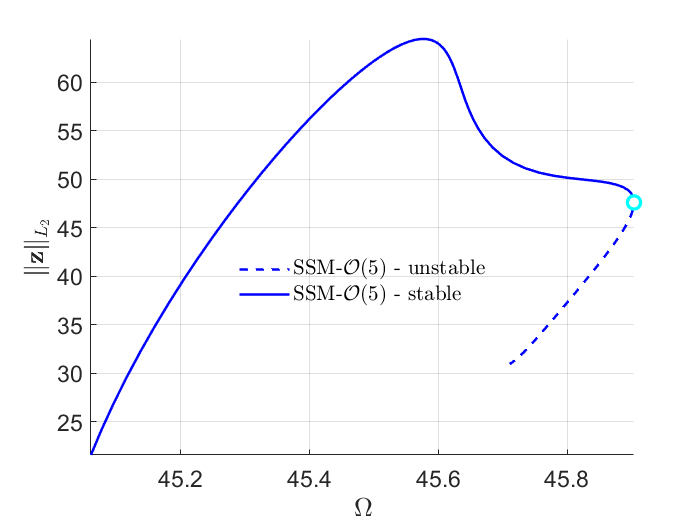

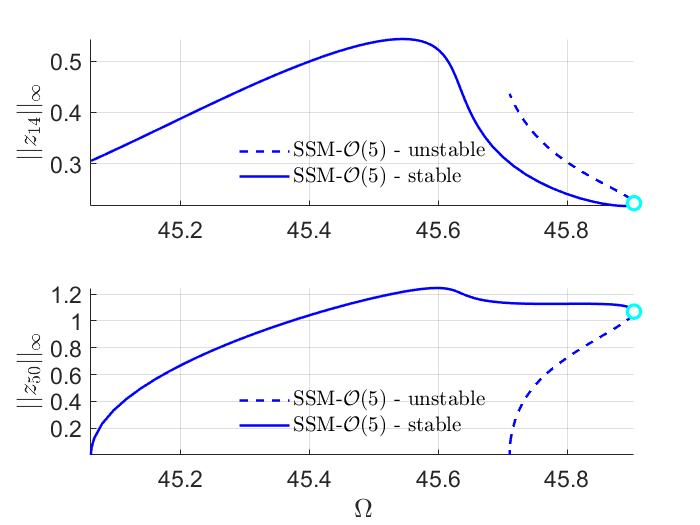

bd = coco_bd_read('isol-5.ep');
BPlabs = coco_bd_labs(bd, 'BP');
set(S.contOptions, 'PtMX', [100,0]);    
S.SSM_BP2ep('o5-bp1','isol-5',BPlabs(1),'freq',omegaRange,outdof);

We also perform branch switching at the other BP point. It is expected that the results are the same as the above.


 Run='o5-bp2.ep': Continue equilibria along secondary branch from label 12 of run isol-5.

 STEP      TIME        ||U||  LABEL  TYPE            om         Rez1         Rez2         Imz1         Imz2          eps
    0  00:00:00   7.1605e+01      1  EP      4.5710e+01   0.0000e+00   1.6032e+01   0.0000e+00   1.4736e+01   1.0000e-01
    1  00:00:00   7.1605e+01      2  SN      4.5710e+01   2.7489e-04   1.6032e+01  -5.2428e-04   1.4736e+01   1.0000e-01
    1  00:00:00   7.1605e+01      3  FP      4.5710e+01   6.6615e-03   1.6032e+01  -1.2705e-02   1.4736e+01   1.0000e-01
   10  00:00:00   7.1950e+01      4          4.5725e+01   4.5194e+00   1.5840e+01  -9.1037e+00   1.1972e+01   1.0000e-01
   20  00:00:01   7.7255e+01      5          4.5862e+01   1.5220e+01   1.1561e+01  -2.2038e+01   5.4666e+00   1.0000e-01
   30  00:00:01   8.0239e+01      6  FP      4.5903e+01   2.3336e+01   9.9355e+00  -2.1093e+01   4.8806e+00   1.0000e-01
   30  00:00:01   8.0239e+01      7  SN      4.5903e+01   2.3

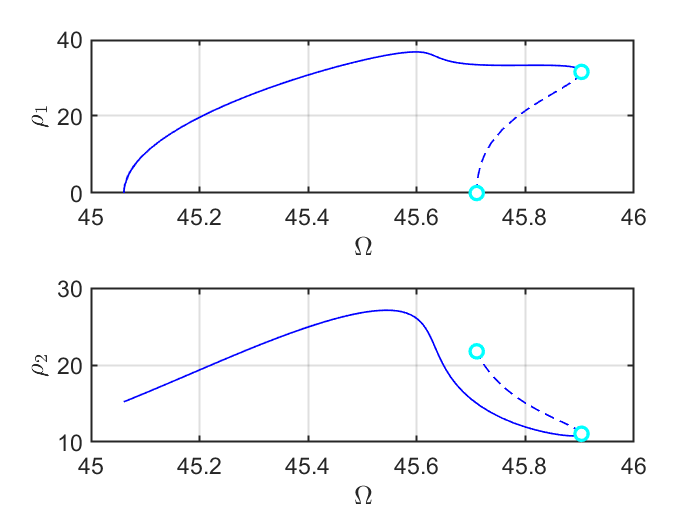

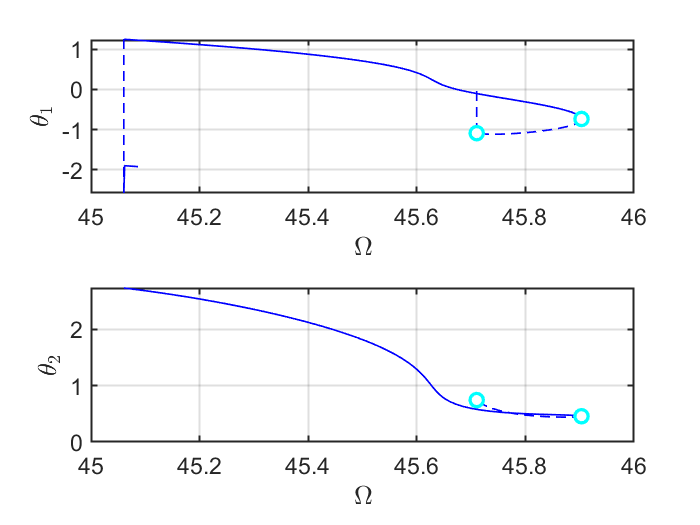

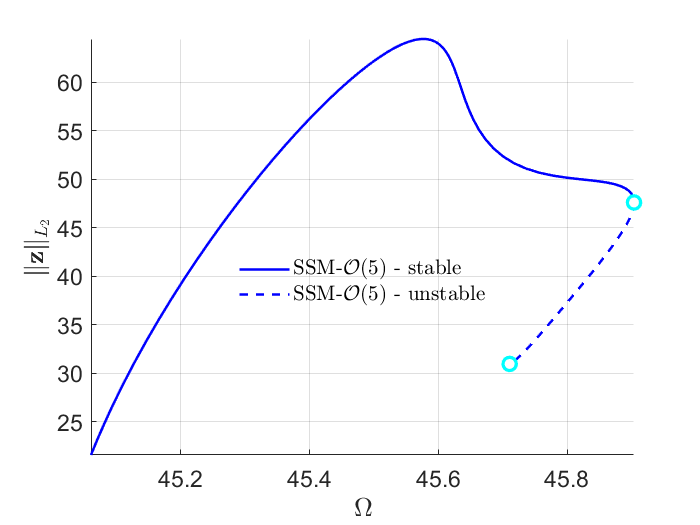

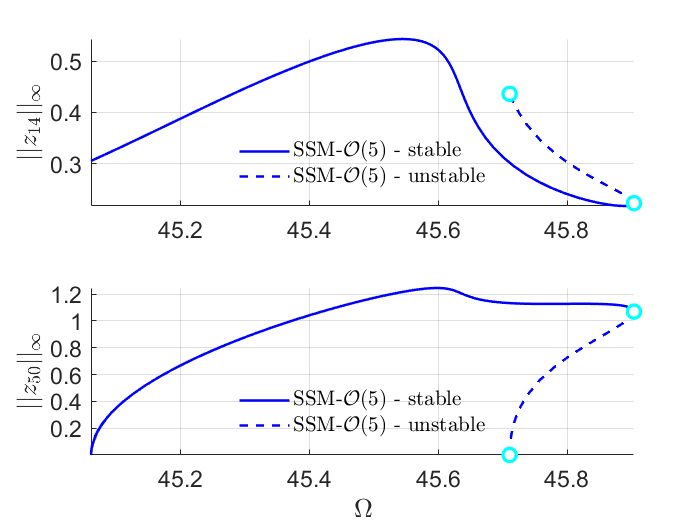

S.SSM_BP2ep('o5-bp2','isol-5',BPlabs(2),'freq',omegaRange,outdof);

Now we are ready to put two branches of solution at the same figure.

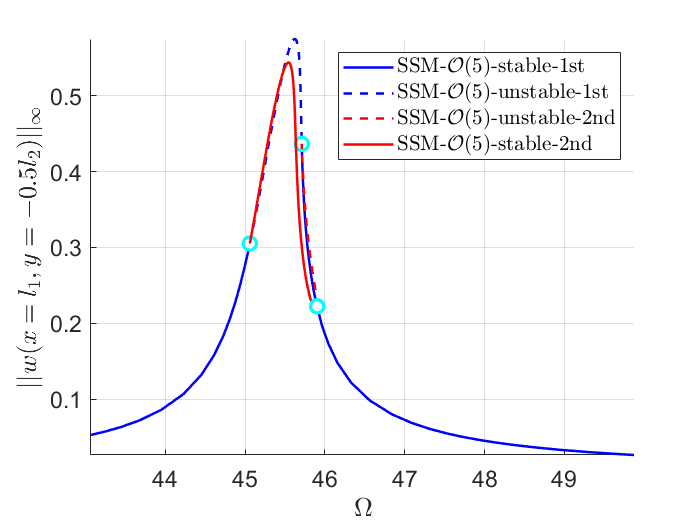

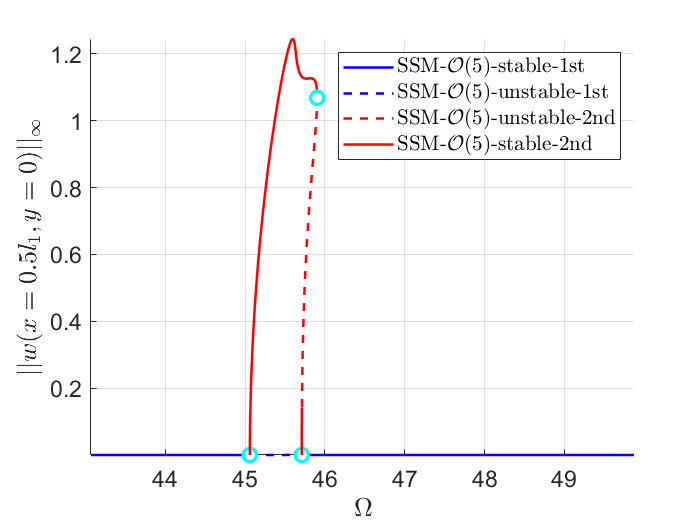

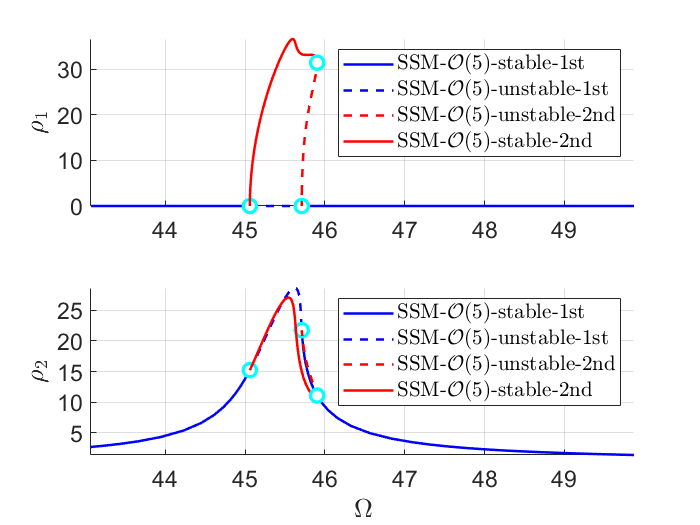

thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
FRC_O5 = load('data\isol-5.ep\SSMep.mat');
FRC_O5 = FRC_O5.FRC;
FRCbp = load("data\o5-bp1.ep\SSMep.mat");
FRCbp = FRCbp.FRC;
FRCs = {FRC_O5,FRCbp};
color = {'b','r','m','b','g'};
for k=1:numel(FRCs)
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    if k==1
        legs = 'SSM-$\mathcal{O}(5)$-unstable-1st';
        legu = 'SSM-$\mathcal{O}(5)$-stable-1st';
    else
        legs = 'SSM-$\mathcal{O}(5)$-unstable-2nd';
        legu = 'SSM-$\mathcal{O}(5)$-stable-2nd';        
    end
    figure(204); hold on
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||w(x=l_1,y=-0.5l_2)||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
    figure(205); hold on
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,2),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,2),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,2),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||w(x=0.5l_1,y=0)||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight;     
    figure(206); 
    subplot(2,1,1); hold on
    plot_stab_lines(FRC.om,FRC.rho(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.rho(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.rho(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    ylabel('$\rho_1$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
    subplot(2,1,2); hold on
    plot_stab_lines(FRC.om,FRC.rho(:,2),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.rho(SNidx,2),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.rho(HBidx,2),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$\rho_2$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight;     
end